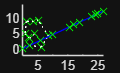

% rotation of cities into straight line for rotation homotopy
cities = [8.5, 6.2, 3.5, 5.1, 4.0, 0.8, 2.4, 1.2, 1.8, 2.4; 4.2, 0.5, 9.0, 9.4, 4.9, 4.9, 3.4, 9.0, 3.7, 1.1];
corners = [0, 10, 10, 0; 0, 0, 10, 10];
sequence = [1, 10, 2, 1, 4, 3, 8, 6, 9, 7, 5];

figure(1)
hold on
% plot city points
scatter([corners(1, sequence(1)), cities(1, :)], [corners(2, sequence(1)), cities(2, :)], 'xg')
% axis([0 10 0 10])

% plot lines between each
for i = 1:10
    if i == 1
        plot([corners(1, sequence(1)), cities(1, sequence(2))], [corners(2, sequence(1)), cities(2, sequence(2))], ':w')
    else
        plot([cities(1, sequence(i)), cities(1, sequence(i+1))], [cities(2, sequence(i)), cities(2, sequence(i+1))], ':w')
    end
end

% rotate each point about the previous such that all points are collinear
% grab overall direction:
u = [cities(1, sequence(2)) - corners(1, sequence(1)); cities(2, sequence(2)) - corners(2, sequence(1))];
u = u/norm(u); % force unit vector
newPoints(:, 1) = cities(:, sequence(2));
d = zeros(1, 9);
theta = zeros(1, 9);
for i = 1:9
    % vector of points:
    v = [cities(1, sequence(i+2)) - cities(1, sequence(i+1)), cities(2, sequence(i+2)) - cities(2, sequence(i+1))];

    % radius for rotation:
    d(i) = norm(v);

    % angle of rotation:
    theta(i) = acos(dot(u, v)/d(i))*sign(dot(cross([u', 0], [v, 0]), [0, 0, 1]));

    % place new point at distance d along vector u
    newPoints(:, i+1) = newPoints(:, i) + d(i)*u;
end

for i = 1:10
    if i == 1
        plot([corners(1, sequence(1)), newPoints(1, sequence(2))], [corners(2, sequence(1)), newPoints(2, sequence(2))], '--b')
    else
        plot([newPoints(1, sequence(i)), newPoints(1, sequence(i+1))], [newPoints(2, sequence(i)), newPoints(2, sequence(i+1))], '--b')
    end
end

scatter([corners(1, sequence(1)), newPoints(1, :)], [corners(2, sequence(1)), newPoints(2, :)], 'xg')
axis equal


r = 1;
meshpoints = 11;
angle = atan2(u(2),u(1));
times = zeros(1, 10);
dist = zeros(1, 10);
dist(1) = (newPoints(1, 1)^2+newPoints(2, 1)^2)^0.5;
times(1) = sqrt(2*dist(1));
for i = 2:10
    dist(i) = ((newPoints(1, i)-newPoints(1, i-1))^2+(newPoints(2, i) - newPoints(2, i-1))^2)^0.5;
    v = sum(times);
    times(i) = (-2*v+sqrt(4*v^2+8*dist(i)))/2;
end
T = linspace(0, 1, meshpoints);
S = zeros(80, meshpoints);
S(3, :) = angle*ones(1, meshpoints);
S(1, :) = (0.5*(T*times(1)).^2)*cos(angle);
S(2, :) = (0.5*(T*times(1)).^2)*sin(angle);
S(4, :) = T*times(1);
S(5, :) = (-1-r/2)./(S(4, :)*sec(angle));
S(6, :) = S(5, :)*tan(angle);
S(7, :) = zeros(1, meshpoints);
S(8, :) = -2/r*ones(1, meshpoints);
for i = 2:10
    time = sum(times(1:(i-1)))+T*times(i);
    S(8*i-5, :) = angle*ones(1, meshpoints);
    S(8*i-7, :) = 0.5*(time).^2*cos(angle);
    S(8*i-6, :) = 0.5*(time).^2*sin(angle);
    S(8*i-4, :) = time;
    S(8*i-3, :) = (-1-r/2)./(S(8*i-4, :)*sec(angle));
    S(8*i-2, :) = S(8*i-3, :)*tan(angle);
    S(8*i-1, :) = zeros(1, meshpoints);
    S(8*i, :) = -2/r*ones(1, meshpoints);
end
solinit.x = T;
solinit.y = S;
solinit.parameters = times;